clear
clc

## Define element_information struct array in MATLAB


element_information(1).node = [0, 2];
element_information(1).E = 30 * 10^6;
element_information(1).area = 10;
element_information(1).length = 15*12;
element_information(1).innertia = 150;
element_information(1).theta = pi/2;
element_information(1).BCd.node1 = [0, 0, 'none'];
element_information(1).BCd.node2 = ['none', 'none', 'none'];
element_information(1).BCf.node1 = ['reaction', 'reaction', 'none'];
element_information(1).BCf.node2 = [2400, 'none', 'none'];

element_information(2).node = [1, 3];
element_information(2).E = 30 * 10^6;
element_information(2).area = 10;
element_information(2).length = 15*12;
element_information(2).innertia = 150;
element_information(2).theta = pi/2;
element_information(2).BCd.node1 = [0, 0, 'none'];
element_information(2).BCd.node2 = ['none', 'none', 'none'];
element_information(1).BCf.node1 = ['reaction', 'reaction', 'none'];
element_information(1).BCf.node2 = [2400, 'none', 'none'];


element_information(3).node = [2, 4];
element_information(3).E = 30 * 10^6;
element_information(3).area = 10;
element_information(3).length = 15*12;
element_information(3).innertia = 150;
element_information(3).theta = pi/2;
element_information(3).BCd.node1 = ['none', 'none', 'none'];
element_information(3).BCd.node2 = ['none', 'none', 'none'];
element_information(3).BCf.node1 = [2400, 'none', 'none'];
element_information(3).BCf.node2 = ['none', 'none', 3000*12];

element_information(4).node = [3, 5];
element_information(4).E = 30 * 10^6;
element_information(4).area = 10;
element_information(4).length = 15*12;
element_information(4).innertia = 150;
element_information(4).theta = pi/2;
element_information(4).BCd.node1 = ['none', 'none', 'none'];
element_information(4).BCd.node2 = ['none', 'none', 'none'];
element_information(4).BCf.node1 = ['none', 'none', 'none'];
element_information(4).BCf.node2 = ['none', 'none', 'none'];

element_information(5).node = [2, 3];
element_information(5).E = 30 * 10^6;
element_information(5).area = 12;
element_information(5).length = 25*12;
element_information(5).innertia = 300;
element_information(5).theta = 0;
element_information(5).BCd.node1 = ['none', 'none', 'none'];
element_information(5).BCd.node2 = ['none', 'none', 'none'];
element_information(5).BCf.node1 = [2400, 'none', 'none'];
element_information(5).BCf.node2 = ['none', 'none', 'none'];

element_information(6).node = [4, 5];
element_information(6).E = 30 * 10^6;
element_information(6).area = 12;
element_information(6).length = 25*12;
element_information(6).innertia = 200;
element_information(6).theta = 0;
element_information(6).BCd.node1 = ['none', 'none', 'none'];
element_information(6).BCd.node2 = ['none', 'none', 'none'];
element_information(6).BCf.node1 = ['none', 'none', 250];
element_information(6).BCf.node2 = ['none', 'none', 'none'];

% cross member from bot2top, r2l
L_cross = sqrt((25*12)^2 + (15*12)^2);

element_information(7).node = [0, 3];
element_information(7).E = 30 * 10^6;
element_information(7).area = 2;
element_information(7).length = L_cross;
element_information(7).innertia = 1;
element_information(7).theta = atan2(15, 25);
element_information(7).BCd.node1 = [0, 0, 'none'];
element_information(7).BCd.node2 = ['none', 'none', 'none'];
element_information(7).BCf.node1 = ['reaction', 'reaction', 'none'];
element_information(7).BCf.node2 = ['none', 'none', 'none'];

element_information(8).node = [2, 1];
element_information(8).E = 30 * 10^6;
element_information(8).area = 2;
element_information(8).length = L_cross;
element_information(8).innertia = 1;
element_information(8).theta = -atan2(15, 25);
element_information(8).BCd.node1 = ['none', 'none', 'none'];
element_information(8).BCd.node2 = [0, 0, 'none'];
element_information(8).BCf.node1 = [2400, 'none', 'none'];
element_information(8).BCf.node2 = ['reaction', 'reaction', 'none'];

element_information(9).node = [2, 5];
element_information(9).E = 30 * 10^6;
element_information(9).area = 2;
element_information(9).length = L_cross;
element_information(9).innertia = 1;
element_information(9).theta = atan2(15, 25);
element_information(9).BCd.node1 = ['none', 'none', 'none'];
element_information(9).BCd.node2 = ['none', 'none', 'none'];
element_information(9).BCf.node1 = [2400, 'none', 'none'];
element_information(9).BCf.node2 = ['none', 'none', 'none'];

element_information(10).node = [4, 3];
element_information(10).E = 30 * 10^6;
element_information(10).area = 2;
element_information(10).length = L_cross;
element_information(10).innertia = 1;
element_information(10).theta = -atan2(15, 25);
element_information(10).BCd.node1 = ['none', 'none', 'none'];
element_information(10).BCd.node2 = ['none', 'none', 'none'];
element_information(10).BCf.node1 = ['none', 'none', 250];
element_information(10).BCf.node2 = ['none', 'none', 'none'];

%% end ofDefine node_information struct array in MATLAB



## problem hypermarameters MANULLAY INPUT HERE


total_node = 6;
DOF = 3;
%% end of problem hypermarameters MANULLAY INPUT HERE


## construct K


K_global = zeros(total_node * DOF);

for i = 1:numel(element_information)
    % get elemen_i properties data 
    element = element_information(i);

    node = element.node;
    E = element.E;
    A = element.area;
    I = element.innertia;
    L = element.length;
    theta = element.theta;

    % Do something with the data
    % Calculate K based on the provided formula

    c1 = E * A / L;
    c2 = E * I / (L^3); 

    % Get node number of element 
    i = node(1);
    j = node(2);

    if DOF == 3
        i = node(1)*DOF;
        j = node(2)*DOF;
        K = [c1,    0,          0,          -c1,    0,          0; 
             0,     12*c2,      6*L*c2,     0,      -12*c2,     6*L*c2;
             0,     6*L*c2,     4*(L^2)*c2, 0,      -6*L*c2,    2*(L^2)*c2;
             -c1,   0,          0,          c1,     0,          0;
             0,     -12*c2,     -6*L*c2,    0,      12*c2,      -6*L*c2;
             0,     6*L*c2,     2*(L^2)*c2, 0,      -6*L*c2,    4*(L^2)*c2;

        ];
        % Local to global
        if theta ~= 0
            T = Local_Global_3UVM(theta); % Local_to_Global function 
            K = T' * K * T;
        end
        
        K_global(i+1, i+1) = K_global(i+1, i+1) + K(1,1);
        K_global(i+1, i+2) = K_global(i+1, i+2) + K(1,2);
        K_global(i+1, i+3) = K_global(i+1, i+3) + K(1,3);
        K_global(i+1, j+1) = K_global(i+1, j+1) + K(1,4);
        K_global(i+1, j+2) = K_global(i+1, j+2) + K(1,5);
        K_global(i+1, j+3) = K_global(i+1, j+3) + K(1,6);
        
        K_global(i+2, i+1) = K_global(i+2, i+1) + K(2,1);
        K_global(i+2, i+2) = K_global(i+2, i+2) + K(2,2);
        K_global(i+2, i+3) = K_global(i+2, i+3) + K(2,3);
        K_global(i+2, j+1) = K_global(i+2, j+1) + K(2,4);
        K_global(i+2, j+2) = K_global(i+2, j+2) + K(2,5);
        K_global(i+2, j+3) = K_global(i+2, j+3) + K(2,6);

        K_global(i+3, i+1) = K_global(i+3, i+1) + K(3,1);
        K_global(i+3, i+2) = K_global(i+3, i+2) + K(3,2);
        K_global(i+3, i+3) = K_global(i+3, i+3) + K(3,3);
        K_global(i+3, j+1) = K_global(i+3, j+1) + K(3,4);
        K_global(i+3, j+2) = K_global(i+3, j+2) + K(3,5);
        K_global(i+3, j+3) = K_global(i+3, j+3) + K(3,6);

        K_global(j+1, i+1) = K_global(j+1, i+1) + K(4,1);
        K_global(j+1, i+2) = K_global(j+1, i+2) + K(4,2);
        K_global(j+1, i+3) = K_global(j+1, i+3) + K(4,3);
        K_global(j+1, j+1) = K_global(j+1, j+1) + K(4,4);
        K_global(j+1, j+2) = K_global(j+1, j+2) + K(4,5);
        K_global(j+1, j+3) = K_global(j+1, j+3) + K(4,6);

        K_global(j+2, i+1) = K_global(j+2, i+1) + K(5,1);
        K_global(j+2, i+2) = K_global(j+2, i+2) + K(5,2);
        K_global(j+2, i+3) = K_global(j+2, i+3) + K(5,3);
        K_global(j+2, j+1) = K_global(j+2, j+1) + K(5,4);
        K_global(j+2, j+2) = K_global(j+2, j+2) + K(5,5);
        K_global(j+2, j+3) = K_global(j+2, j+3) + K(5,6);


        K_global(j+3, i+1) = K_global(j+3, i+1) + K(6,1);
        K_global(j+3, i+2) = K_global(j+3, i+2) + K(6,2);
        K_global(j+3, i+3) = K_global(j+3, i+3) + K(6,3);
        K_global(j+3, j+1) = K_global(j+3, j+1) + K(6,4);
        K_global(j+3, j+2) = K_global(j+3, j+2) + K(6,5);
        K_global(j+3, j+3) = K_global(j+3, j+3) + K(6,6);

    end


end
%% end of construct K

K_global

K_global = 1.0e+08 *

    0.0014    0.0008   -0.0083         0         0         0   -0.0001   -0.0000   -0.0083   -0.0013   -0.0008   -0.0000         0         0         0         0         0         0
    0.0008    0.0171    0.0000         0         0         0   -0.0000   -0.0167    0.0000   -0.0008   -0.0005    0.0000         0         0         0         0         0         0
   -0.0083    0.0000    1.0034         0         0         0    0.0083   -0.0000    0.5000    0.0000   -0.0000    0.0017         0         0         0         0         0         0
         0         0         0    0.0014   -0.0008   -0.0083   -0.0013    0.0008   -0.0000   -0.0001   -0.0000   -0.0083         0         0         0         0         0         0
         0         0         0   -0.0008    0.0171   -0.0000    0.0008   -0.0005   -0.0000   -0.0000   -0.0167    0.0000         0         0         0         0         0         0
         0         0         0   -0.0083   -0.0000    1.0034    0.0000   

## boundry condition


% boundry index in global matrix: 
bc_index = [];
for idx = 1:numel(element_information)
    element = element_information(idx);
    node = element.node;
    i = node(1);
    j = node(2);
    idx = idx - 1;
    if element.BCd.node1(1) ~= 'none'
        index = i*3 + 1
        bc_index = [bc_index, index];
        end

    if element.BCd.node1(2) ~= 'none'
        index = i*3 + 2
        bc_index = [bc_index, index];
        end

    if element.BCd.node1(3) ~= 'none'
        index = i*3 + 3
        bc_index = [bc_index, index];
        end

    if element.BCd.node2(1) ~= 'none'
        index = j*3 + 1
        bc_index = [bc_index, index];
        end

    if element.BCd.node2(2) ~= 'none'
        index = j*3 + 2
        bc_index = [bc_index, index];
        end

    if element.BCd.node2(3) ~= 'none'
        index = j*3 + 3
        bc_index = [bc_index, index];
        end
    
end 

index = 1

index = 2

index = 4

index = 5

index = 1

index = 2

index = 4

index = 5

% Display boundary index
bc_index = unique(bc_index)

bc_index =      1     2     4     5


bc_val = [0, 0, 0, 0]

bc_val =      0     0     0     0


F = [0,0,0,  0,0,0,  2400,0,0,  0,0,0,  1200,0,250,  0,0,0]

F =            0           0           0           0           0           0        2400           0           0           0           0           0        1200           0         250           0           0           0


## reduction


Fred=F';
Kred = K_global;
clear length
for i = 1:length(bc_index)
    reduc = K_global(:,bc_index(i)) * bc_val(i);
    Fred=Fred - reduc;

    Kred(:,bc_index(i)) = 0;
    Kred(bc_index(i),:) = 0;
    Kred(bc_index(i),bc_index(i)) = 1;
end

for i =1:length(bc_index)
    Fred(bc_index(i))=bc_val(i);
end

Kred

Kred = 1.0e+08 *

    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0034         0         0         0    0.0083   -0.0000    0.5000    0.0000   -0.0000    0.0017         0         0         0         0         0         0
         0         0         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.0034    0.0000    0.0

## solve


displacement=Kred\Fred

displacement =          0
         0
   -0.0001
         0
         0
   -0.0001
    0.0152
    0.0011
   -0.0000
    0.0143


Freact=K_global*displacement

Freact = 1.0e+03 *

   -1.7464
   -2.8792
    0.0000
   -1.8536
    2.8792
    0.0000
    2.4000
    0.0000
    0.0000
    0.0000


%% end of solve


## plotting


p1 = [0,    0];
p2 = [300,  0];
p3 = [0,    15*12];
p4 = [300,  15*12]; 
p5 = [0,    15*12*2];
p6 = [300,  15*12*2];

% Plot the points
plot([p1(1), p3(1)], [p1(2), p3(2)], '-', 'Color', 'b'); % Connect p1 to p3
hold on;
plot([p1(1), p4(1)], [p1(2), p4(2)], '-', 'Color', 'b'); % Connect p1 to p4

plot([p2(1), p3(1)], [p2(2), p3(2)], '-', 'Color', 'b'); % Connect p2 to p3
plot([p2(1), p4(1)], [p2(2), p4(2)], '-', 'Color', 'b'); % Connect p2 to p3

plot([p3(1), p4(1)], [p3(2), p4(2)], '-', 'Color', 'b'); % Connect p3 to p4
plot([p3(1), p5(1)], [p3(2), p5(2)], '-', 'Color', 'b'); % Connect p3 to p5
plot([p3(1), p6(1)], [p3(2), p6(2)], '-', 'Color', 'b'); % Connect p3 to p6

plot([p4(1), p5(1)], [p4(2), p5(2)], '-', 'Color', 'b'); % Connect p4 to p5
plot([p4(1), p6(1)], [p4(2), p6(2)], '-', 'Color', 'b'); % Connect p4 to p6

plot([p5(1), p6(1)], [p5(2), p6(2)], '-', 'Color', 'b'); % Connect p5 to p6


% update coordinates with scale factor 
% Iterate over each point and update its coordinates based on d and f
f = 1000;
d = displacement'

d =          0         0   -0.0001         0         0   -0.0001    0.0152    0.0011   -0.0000    0.0143   -0.0011   -0.0000    0.0211    0.0014   -0.0000    0.0206   -0.0013   -0.0000


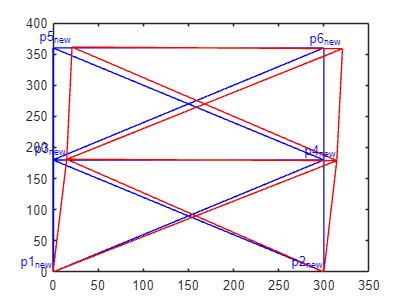

points = {p1, p2, p3, p4, p5, p6};
new_points = cell(size(points));
for i = 1:numel(points)
    % Calculate the new coordinates
    new_x = points{i}(1) + f * d(3*i - 2);
    new_y = points{i}(2) + f * d(3*i - 1);
    
    % Store the new coordinates in variables with appropriate names
    eval(sprintf('p%d_new = [%f, %f];', i, new_x, new_y));
    
    % Store the new coordinates in a cell array
    new_points{i} = [new_x, new_y];
end

% Plot the updated points
hold on;
plot([p1_new(1), p3_new(1)], [p1_new(2), p3_new(2)], '-', 'Color', 'r'); % Connect p1 to p3
plot([p1_new(1), p4_new(1)], [p1_new(2), p4_new(2)], '-', 'Color', 'r'); % Connect p1 to p4

plot([p2_new(1), p3_new(1)], [p2_new(2), p3_new(2)], '-', 'Color', 'r'); % Connect p2 to p3
plot([p2_new(1), p4_new(1)], [p2_new(2), p4_new(2)], '-', 'Color', 'r'); % Connect p2 to p4

plot([p3_new(1), p4_new(1)], [p3_new(2), p4_new(2)], '-', 'Color', 'r'); % Connect p3 to p4
plot([p3_new(1), p5_new(1)], [p3_new(2), p5_new(2)], '-', 'Color', 'r'); % Connect p3 to p5
plot([p3_new(1), p6_new(1)], [p3_new(2), p6_new(2)], '-', 'Color', 'r'); % Connect p3 to p6

plot([p4_new(1), p5_new(1)], [p4_new(2), p5_new(2)], '-', 'Color', 'r'); % Connect p4 to p5
plot([p4_new(1), p6_new(1)], [p4_new(2), p6_new(2)], '-', 'Color', 'r'); % Connect p4 to p6

plot([p5_new(1), p6_new(1)], [p5_new(2), p6_new(2)], '-', 'Color', 'r'); % Connect p5 to p6

hold off;

% Add labels to the updated points
labels = {'p1_new', 'p2_new', 'p3_new', 'p4_new', 'p5_new', 'p6_new'};
for i = 1:numel(labels)
    text(eval(sprintf('p%d_new(1)', i)), eval(sprintf('p%d_new(2)', i)), labels{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'b');
end


%% end of plotting


## Stress for elemenet with node connection 2-4

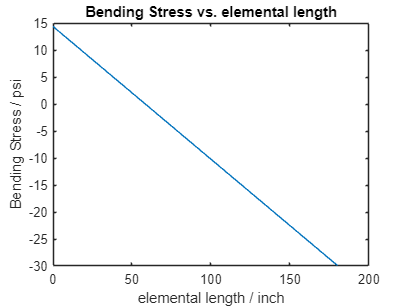

% axial stress and bending stress 
%{
element_information(3).node = [2, 4];
element_information(3).E = 30 * 10^6;
element_information(3).area = 10;
element_information(3).length = 15*12;
element_information(3).innertia = 150;
element_information(3).theta = pi/2;
element_information(3).BCd.node1 = ['none', 'none', 'none'];
element_information(3).BCd.node2 = ['none', 'none', 'none'];
element_information(3).BCf.node1 = [2400, 'none', 'none'];
element_information(3).BCf.node2 = ['none', 'none', 250];
%}

% Define the range of x values
x_values = linspace(0, 180, 100); % Adjust the number of points as needed

% Initialize an array to store bending stresses
bend_stress_values = zeros(size(x_values));

% Get displacement_e3 for the current x value
i = element_information(3).node(1);
j = element_information(3).node(2);
d([i*3+1, j*3+1]) = -d([i*3+1, j*3+1]);
bend_stress_displacement_e3 = d([i*3+1, i*3+3, j*3+1, j*3+3]);
bend_stress_displacement_e3 = bend_stress_displacement_e3';

normal_stress_displacement_e3 = d([i*3+2, j*3+2]);
normal_stress_displacement_e3 = normal_stress_displacement_e3';

% neutrual line 
y = 3;
% Iterate over each x value
for idx = 1:numel(x_values)
    x = x_values(idx);
    
    % Calculate B as a function of x
    L = element_information(3).length;
    B_bending = (1/L^3) * [12*x-6*L, 6*L*x-4*L^2, -12*x+6*L, 6*L*x-2*L^2];
    B_normal =  (1/L) * [-1, 1];


    % Calculate bending stress for the current x value
    bend_stress_values(idx) = -(E*y) * (B_bending * bend_stress_displacement_e3);
    normal_stress_value(idx) = E * B_normal * normal_stress_displacement_e3;
end

% Plot bending stress as a function of x
plot(x_values, bend_stress_values);
xlabel('elemental length / inch');
ylabel('Bending Stress / psi');
title('Bending Stress vs. elemental length');

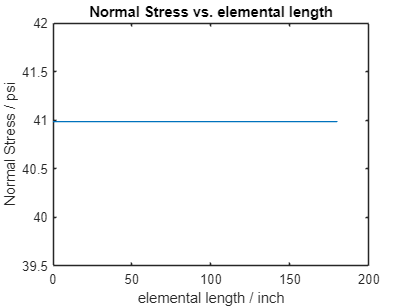


plot(x_values, normal_stress_value);
xlabel('elemental length / inch');
ylabel('Normal Stress / psi');
title('Normal Stress vs. elemental length');